# Modelovanje poremecaja i projektovanje kontrolera na bazi inverzije dinamike na bazi potiskivanja poremecaja - ispostavice se da nije moguce

clc;
close all;
clear variables;

[out_dummy, G, A, B, H, ue] = evalc('linearizacija'); % Poziv f-je linearizacija sa potisnutim ispisom

## Jednačine sistema

syms x1 x2 R L C u E
f(1) = (x2 - u*x2 + u*E) / L;
f(2) = (-x1 + x1*u - x2/R) / C;

## Linearizacija po poremecaju E

A = jacobian(f, [x1, x2])

$$A = \left(\begin{array}{cc} 0 & -\frac{u-1}{L}\\ \frac{u-1}{C} & -\frac{1}{C\,R} \end{array}\right)$$

B = jacobian(f, E)

$$B = \left(\begin{array}{c} \frac{u}{L}\\ 0 \end{array}\right)$$

[L, R, C, E, x2e] = nominalni_parametri();
u = ue;

A = eval(A);
B = eval(B);

## F-ja prenosa poremecaja

syms s
Gd = H * (s*eye(2) - A)^(-1) * B;
s = tf('s');
Gd = minreal(eval(char(Gd)))

Gd =
 
         -3.034e04
  ------------------------
  s^2 + 40.92 s + 1.618e04
 
Continuous-time transfer function.



## Projektovanje kontrolera na bazi potiskivanja poremecaja

### Aproksimacije f-ja prenosa

[Gm,Pm,Wcg,Wcp] = margin(-Gd);
w1d = Wcp

w1d = 212.6970

[w_z, gain] = zero(G);
poles = pole(G);
w_ogranicenje = w_z/4;
G_approx = zpk(-w_z, poles, gain)

G_approx =
 
      2646.8 (s+606.3)
  -------------------------
  (s^2 + 40.92s + 1.618e04)
 
Continuous-time zero/pole/gain model.



K_min = minreal(G_approx^(-1) * Gd)

K_min =
 
   -11.461
  ---------
  (s+606.3)
 
Continuous-time zero/pole/gain model.



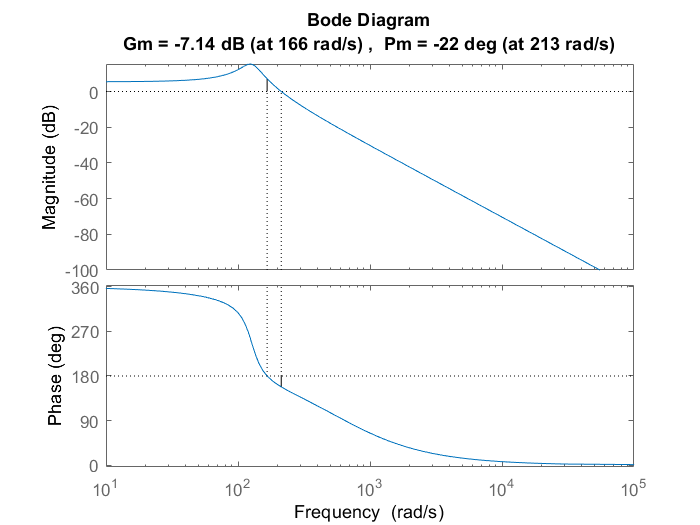

margin(K_min*G)

### Poboljsanje niskofrekventnog pojacanja

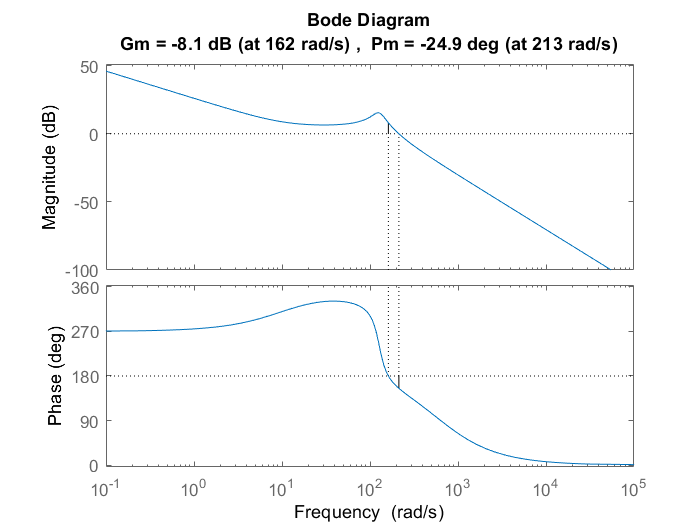

w_ni = w1d / 20;
K = (s + w_ni)/s * K_min;
W = K*G;
% jedna opcija je K = K/10 al pitanje je kakve su performanse
margin(W)

### Popravka preteka faze - lead kontroler - neuspesna

dPhi = pi/3;
a = (1 + sin(dPhi)) / (1 - sin(dPhi));
k = 2;
w1_z = w1d * a^(1/2/k)

w1_z = 410.8990

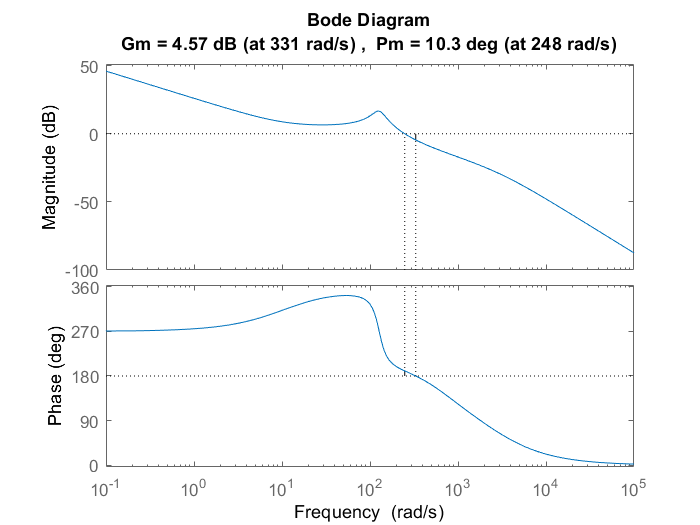

wn = w1_z * a^((1-k)/2/k);
wp = w1_z * a^((1+k)/2/k);
Klead = (s/wn + 1) / (s/wp + 1) * K;
Wlead = Klead*G;
margin(Wlead)

[klead_num, klead_den] = tfdata(Klead, 'v');